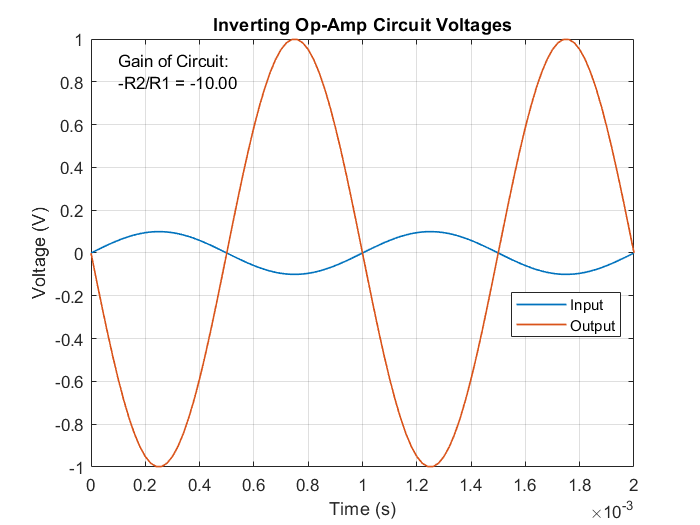

% Code to plot simulation results from ssc_opamp_inverting

% Copyright 2015 The MathWorks, Inc.

% Reuse figure if it exists, else create new figure
try
    figure(h1_ssc_opamp_inverting)
catch
    h1_ssc_opamp_inverting=figure('Name', 'ssc_opamp_inverting');
end

% Generate simulation results if they don't exist
if(~exist('simlog_ssc_opamp_inverting','var'))
    sim('ssc_opamp_inverting')
end

% Get simulation results
temp_vin = simlog_ssc_opamp_inverting.AC_Voltage.v.series;
temp_vout = simlog_ssc_opamp_inverting.Sensor_Vout.Voltage_Sensor.V.series;

% Plot results
plot(temp_vin.time,temp_vin.values,'LineWidth',1);
hold on
plot(temp_vout.time,temp_vout.values,'LineWidth',1);
hold off
text(0.1e-3,0.9,'Gain of Circuit:');
text(0.1e-3,0.8,sprintf('%s %2.2f','-R2/R1 =',-max(temp_vout.values)/max(temp_vin.values)));
grid on
title('Inverting Op-Amp Circuit Voltages');
ylabel('Voltage (V)');
xlabel('Time (s)');
legend({'Input','Output'},'Location','Best');


% Remove temporary variables
clear temp_vin temp_vout